datastore = CLIPDatastore(ImageFolder="./flickr-dataset/Flicker8k_Dataset");
ds = shuffle(datastore, "PercentageToKeep", 0.1)

ds =   CLIPDatastore with no properties.


disp("Number of training images " + numel(ds))

Number of training images 4045


[net,tokenizer] = bert();

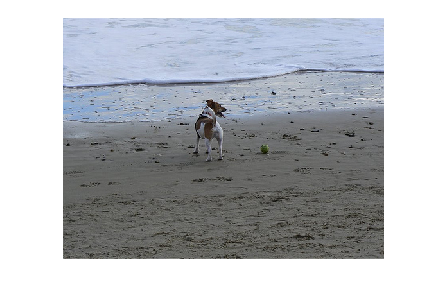

[im, tokens, caption] = read(ds);
imshow(im)

%caption = "A group of horse and their rider be race each other .";
[~, segments] = encode(tokenizer, caption);

dltoken = dlarray(tokens, 'CT');
dlsegment = dlarray(segments{1}, 'CT');
mask = dlarray(ones(1, numel(dlsegment)), 'CT');

pred = predict(net, dltoken, mask, dlsegment);

decodedTokens = decode(tokenizer, tokens)

decodedTokens = "[CLS] a dog on a beach . [SEP]"

disp(size(pred))

   768     8



last = pred(:,1) % Use the [CLS] token but the official CLIP implementation trained their own text encoder and used the last token's embedding

last =   768(C) × 1(T) single dlarray

   -0.2193
   -0.1095
   -0.0425
    1.1517
    0.5936
   -0.3426
   -0.6837
   -0.2077
    0.7877
   -0.4605
   -1.1632
    0.2284
    0.2612
   -0.2545
   -0.2166
   -0.7974
    0.3446
   -0.2151
   -0.4193
   -0.5818
    0.6921
   -0.1864
    0.7180
    0.2961
    0.4455
    0.0748
    0.1377
    0.2942
   -0.5206
    0.4018
   -0.0444
   -0.1254
   -0.8251
    0.4533
   -0.5532
   -0.1809
    0.0878
    0.3696
   -0.3143
   -0.3840
    0.2504
    0.0629
   -0.3399
   -0.0202
    0.3446
   -0.0796
    0.2777
    0.8428
   -0.0054
   -0.0283
   -0.4484
   -0.8255
    0.1242
    0.1402
   -0.3393
    0.2516
    0.5747
   -0.3846
    0.3253
   -0.2936
    0.3090
    0.3249
    0.0592
   -0.4961
    0.1086
    0.3816
   -0.0910
   -0.7139
    0.3283
    0.5450
    0.3923
   -0.5699
   -1.1369
   -0.3899
   -0.7419
   

% NB: Using Bert for batched prediction
[net, tokenizer] = bert() %bert("Model","tiny");

net =   dlnetwork with properties:

         Layers: [129×1 nnet.cnn.layer.Layer]
    Connections: [164×2 table]
     Learnables: [197×3 table]
          State: [0×3 table]
     InputNames: {'input_ids'  'attention_mask'  'seg_ids'}
    OutputNames: {'enc12_layernorm2'}
    Initialized: 1

  View summary with summary.


tokenizer =   bertTokenizer with properties:

        IgnoreCase: 1
      StripAccents: 1
      PaddingToken: "[PAD]"
       PaddingCode: 1
        StartToken: "[CLS]"
         StartCode: 102
      UnknownToken: "[UNK]"
       UnknownCode: 101
    SeparatorToken: "[SEP]"
     SeparatorCode: 103
       ContextSize: 512


paddingValue = tokenizer.PaddingCode;
str = [
    "Coolant is pooling underneath sorter."
    "Sorter blows fuses at start up."
    "There are some very loud rattling sounds coming from the assembler."];
[inputIdsStr, segmentIdsStr] = encode(tokenizer, str);

% The `maskStr` is used to specify the indices of the `paddingValue` so
% that the model ignores the padding
[inputIdsStr, maskStr] = padsequences(inputIdsStr, 2,"PaddingValue",paddingValue);
segmentIdsStr = padsequences(segmentIdsStr, 2,"PaddingValue",paddingValue);

inputIdsStr = dlarray(inputIdsStr, "CTB");
maskStr = dlarray(maskStr, "CTB");
segmentIdsStr = dlarray(segmentIdsStr, "CTB");

predictions = predict(net,inputIdsStr,maskStr,segmentIdsStr);

net = imageEncoder();
randX = dlarray(randn(net.Layers(1).InputSize), 'SSC');
net = dlnetwork(net, randX);
out = predict(net, randX);
disp(size(out))

           1           1        2048



net = textEncoder();
randX = dlarray(randn(1,1,10), 'CBT');
net = dlnetwork(net, Initialize=false);
net = initialize(net, randX, randX, randX)

net =   dlnetwork with properties:

         Layers: [1×1 nnet.cnn.layer.NetworkLayer]
    Connections: [0×2 table]
     Learnables: [197×3 table]
          State: [0×3 table]
     InputNames: {'subnet/input_ids'  'subnet/attention_mask'  'subnet/seg_ids'}
    OutputNames: {'subnet'}
    Initialized: 1

  View summary with summary.



randInputIDs = dlarray(randi(1000, [1 3 10]), 'CBT');
attentionMask = dlarray(ones(size(randInputIDs)), 'CBT');
segmentIDs = dlarray(ones(size(randInputIDs)), 'CBT');

out = predict(net, randInputIDs, attentionMask, segmentIDs);
clsEmbeddings = out(:,:,1);

projHead = projectionHead();
net = dlnetwork(projHead, dlarray(randn(1,2048), 'BC'))

net =   dlnetwork with properties:

         Layers: [1×1 nnet.cnn.layer.NetworkLayer]
    Connections: [0×2 table]
     Learnables: [6×3 table]
          State: [0×3 table]
     InputNames: {'subnet'}
    OutputNames: {'subnet'}
    Initialized: 1

  View summary with summary.


out = predict(net, dlarray(randn(1,2048), 'BC'));

out =   256(C) × 1(B) single dlarray

    0.7783
   -0.0220
    0.4573
    0.8559
    0.4340
   -0.3668
   -0.3328
    0.3062
    1.7508
    0.8042
   -1.7556
   -0.4445
   -0.4793
    0.1797
   -0.8865
    0.0402
   -0.6514
   -1.0311
    0.4522
   -0.5382
   -1.4717
    0.5438
   -0.1362
   -1.0898
   -0.9085
    0.9574
    0.5212
   -0.2271
    0.9898
   -0.7283
   -0.9571
    2.8375
    0.0176
   -0.5402
    0.5068
   -0.6016
   -1.6577
    0.3518
   -0.1909
    0.2499
   -2.0237
   -1.2410
   -0.9853
    1.0750
   -0.2442
   -0.8519
   -0.5367
    0.9952
   -1.4113
    0.7580
    0.5168
    0.4662
    0.4622
   -0.4681
    0.0648
    1.2102
   -1.2912
   -0.6636
    0.1969
    1.6601
   -0.4941
   -1.8388
    0.6253
    1.9885
   -0.2664
   -0.2764
   -1.2384
    0.9500
   -0.4283
   -0.6351
   -1.1980
    2.3252
   -0.1446
   -0.9890
   -0.0948
   -

size(out)

ans =    256     1


## CLIP Interface

load net-gpu-poor-squeezenet-bert-tiny.mat net logTemperature

imageInputSize = net.Layers(1).Layers(1).InputSize(1:2);

imageInputSize =    227   227


clip = CLIP(net, Temperature=exp(logTemperature), ImageInputSize=imageInputSize)

clip =   CLIP with no properties.


% Try encoding some images

% First gather all image paths from the dataset
imgBaseDir = "./flickr-dataset/Flicker8k_Dataset/";
folderContents = dir(imgBaseDir);
boolImagesInFolder = arrayfun(@(x) ~x.isdir, folderContents);
folderContents = folderContents(boolImagesInFolder);
imagePaths = arrayfun(@(s) fullfile(s.folder, s.name), folderContents, UniformOutput=false)

imagePaths = 8091×1 cell array
    {'/home/aibrahee/Documents/openai-clip-matlab/flickr-dataset/Flicker8k_Dataset/1000268201_693b08cb0e.jpg'}
    {'/home/aibrahee/Documents/openai-clip-matlab/flickr-dataset/Flicker8k_Dataset/1001773457_577c3a7d70.jpg'}
    {'/home/aibrahee/Documents/openai-clip-matlab/flickr-dataset/Flicker8k_Dataset/1002674143_1b742ab4b8.jpg'}
    {'/home/aibrahee/Documents/openai-clip-matlab/flickr-dataset/Flicker8k_Dataset/1003163366_44323f5815.jpg'}
    {'/home/aibrahee/Documents/openai-clip-matlab/flickr-dataset/Flicker8k_Dataset/1007129816_e794419615.jpg'}
    {'/home/aibrahee/Documents/openai-clip-matlab/flickr-dataset/Flicker8k_Dataset/1007320043_627395c3d8.jpg'}
    {'/home/aibrahee/Documents/openai-clip-matlab/flickr-dataset/Flicker8k_Dataset/1009434119_febe49276a.jpg'}
    {'/home/aibrahee/Documents/openai-clip-matlab/flickr-dataset/Flicker8k_Dataset/1012212859_01547e3f17.jpg'}
    {'/home/aibrahee/Documents/openai-clip-matlab/flickr-dataset/Flicker8k_Datase

allImagePaths = string(imagePaths);

% Get some random images from the dataset
someImagePaths = randsample(allImagePaths, 10);
% Intentionally duplicate the last image
someImagePaths(end+1) = someImagePaths(end);

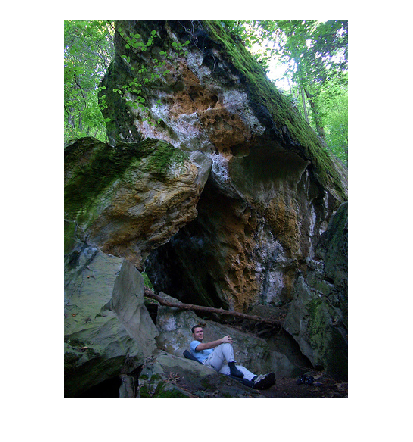

imshow(imread(someImagePaths(1)));

imageEmbeddings = clip.encodeImagesAt(someImagePaths);
textEmbeddings = clip.encodeText("A person by a rock")

im2imLogits = imageEmbeddings' * imageEmbeddings * 40; % temperature of 100
im2imProbs = softmax(im2imLogits, "DataFormat", "SC")

im2imProbs =   11×11 single gpuArray dlarray

    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0

% Visually check that the last 2x2 submatrix is not equal to 1, should be
% around 0.5
disp("The last 2 duplicated images")

The last 2 duplicated images


im2imProbs(end-1:end, end-1:end)

ans =   2×2 single gpuArray dlarray

    0.5000    0.5000
    0.5000    0.5000
